clc, clear, close all
datetime('today')

ans = datetime
   29-May-2023


A = 0.4;
lambda = 1;
k = 2 * pi / lambda;
w = pi;

x = linspace(0, 2, 3000);
t = linspace(0, 300, 3000);
y = A * exp(1i * (k * x - w * t)) + A * exp(1i * (-k * x - w * t));

h = figure(1);
hold on;
ax = gca;

ax.XLim = [0, 2.4];
ax.XAxisLocation = 'origin';
ax.XColor = "k";
xlabel('x, м','Color', 'k');
set(ax,'xticklabel',[]);
set(gca,'XTick',[]);
text(2.32, 0.0098,'\rightarrow', 'Color', 'k');

ax.YLim = [-1, 1];
ax.YColor = "k";
text(0.05, 0.97, '\Re{(y)}, м');
set(ax,'yticklabel',[]);
set(gca,'YTick',[]);
text(-0.02, 0.98,'\uparrow', 'Color', 'k');

title('Стоячая волна', 'FontSize', 12);

Отрисовка:

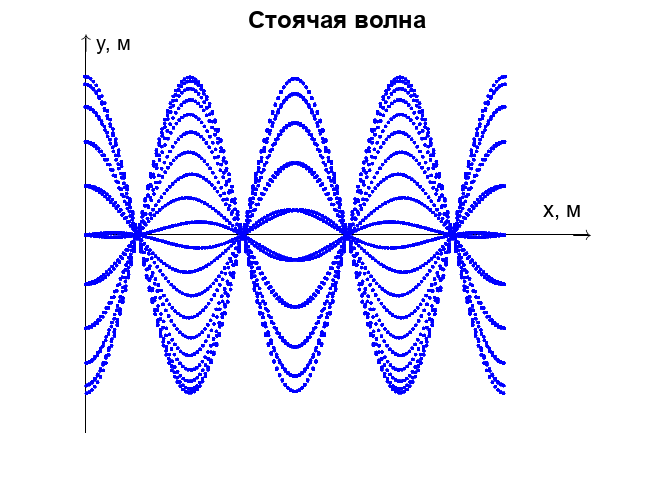

for i = 1:numel(x)
    plot(x(i), real(y(i)), '.', 'Color', 'b');
    drawnow limitrate;
    if (~ishandle(h))
        break;
    end
end